# Berkolaiko-Marzuola-Pelinovsky Quantum Graph Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a dumbbell graph

## Set up the graph structure and coordinates of the problem

Phi = quantumGraphFromTemplate('BMP');

## Set up coordinates on which to plot the solutions

Note that this requires a user-written plotting function. An alternate syntax to the line below is rewrite the call to the quantumGraph constructor above as 

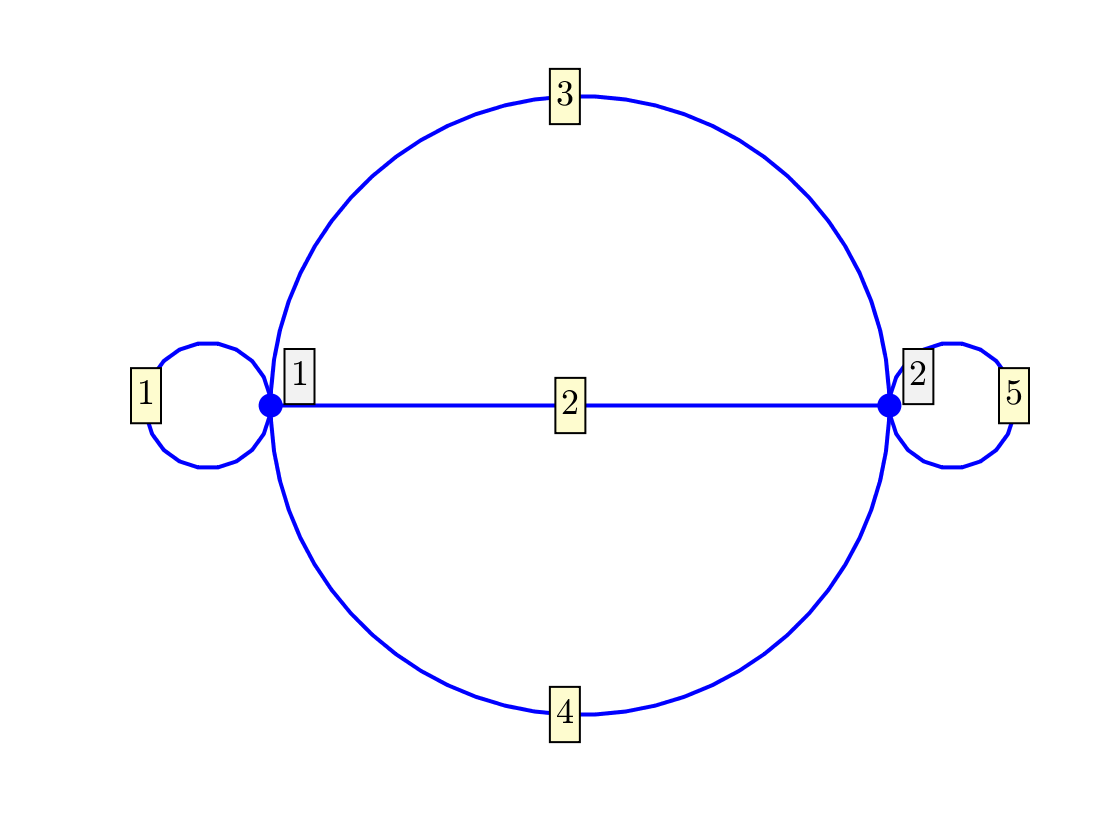

Phi.plot('layout')

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes calculated as positive and sometimes as negative and this screws up the sorting.

[V,lambda]=eig(Phi);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant

## Plot the first few multiplicity-one eigenfunctions

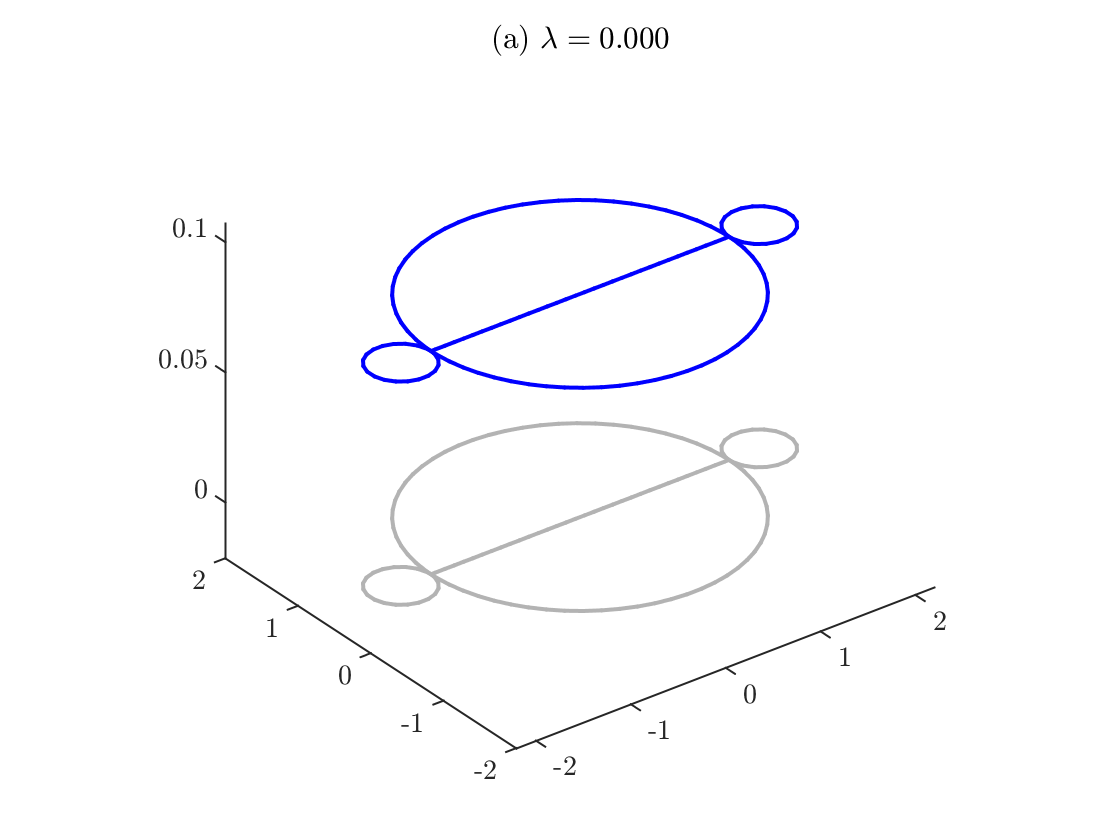

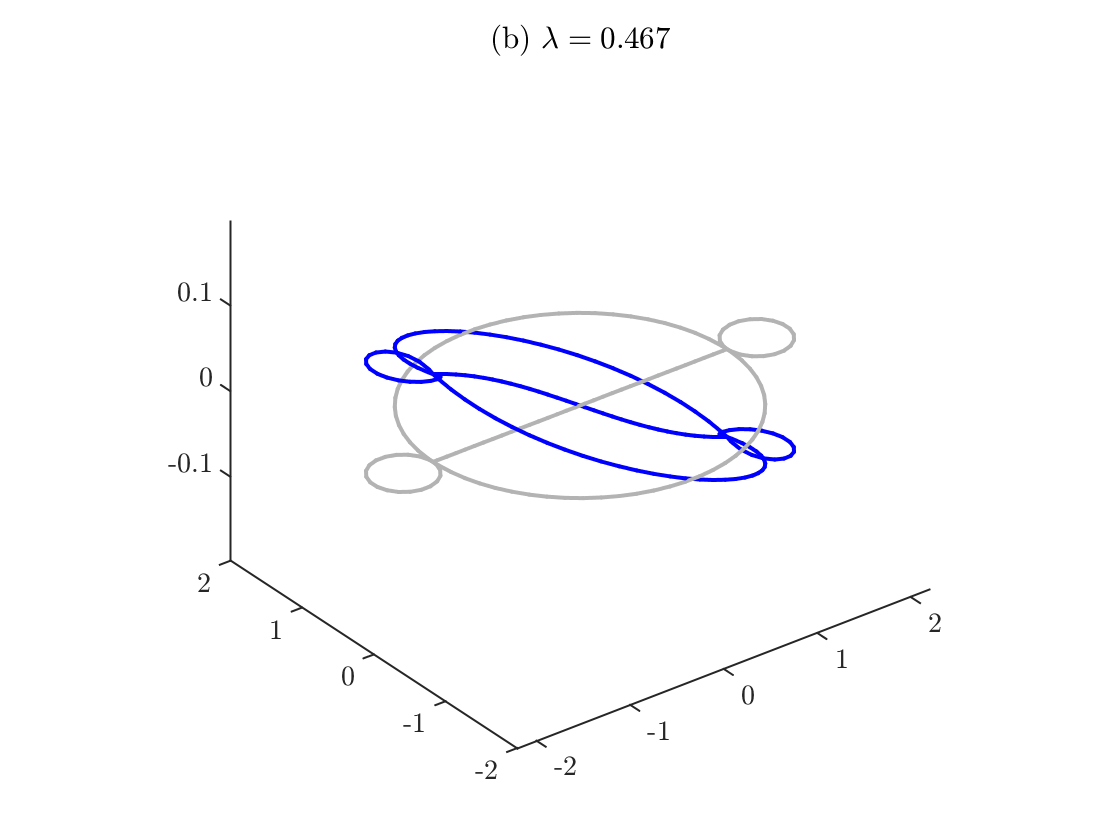

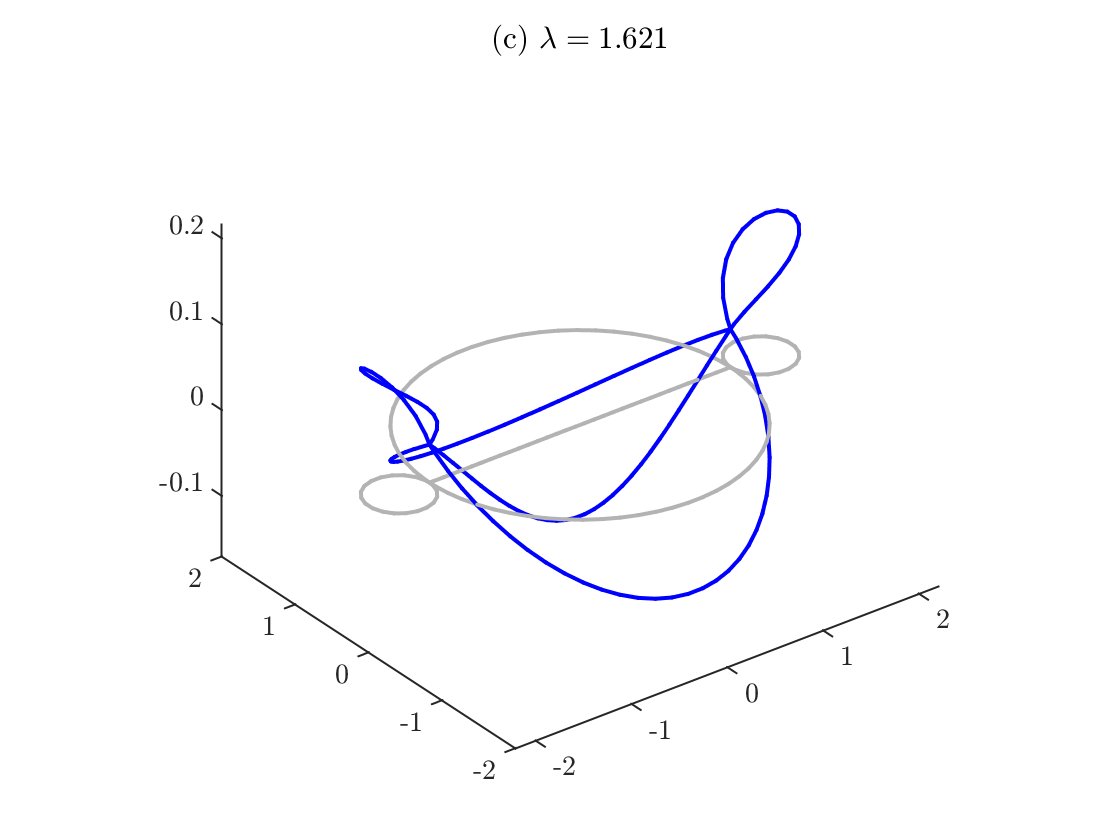

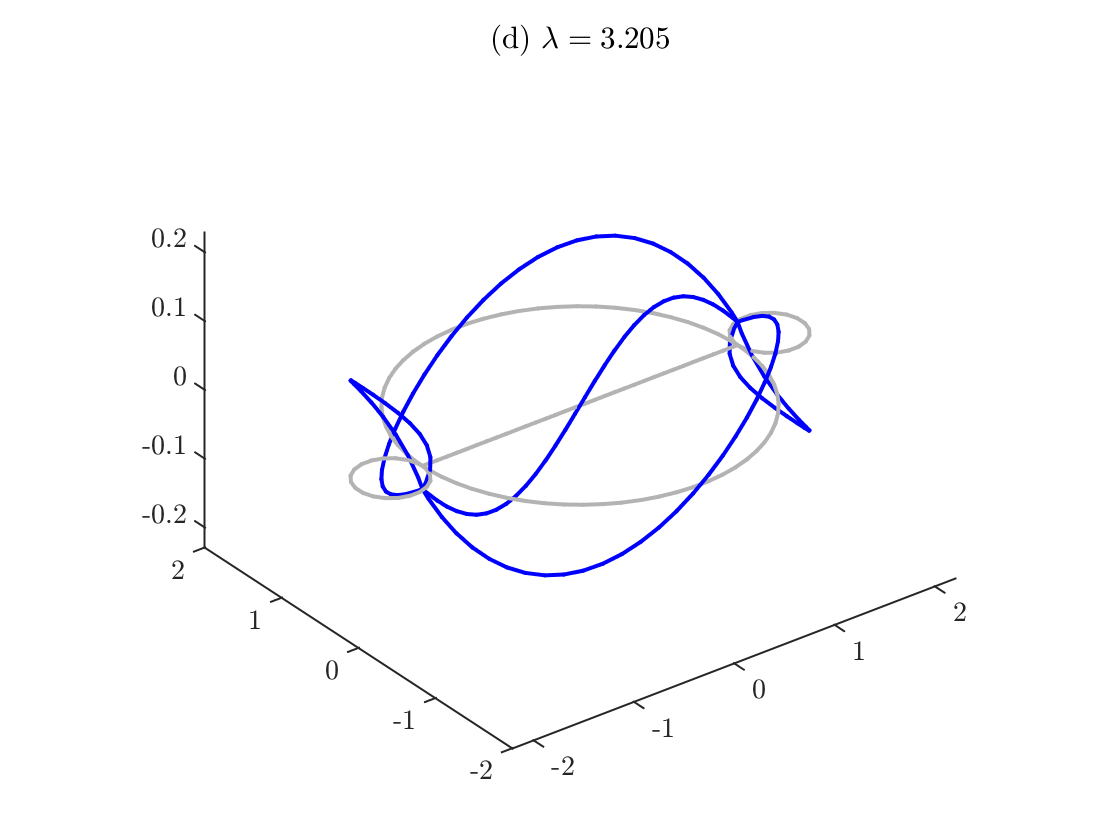

nToPlot=4;
for k=1:nToPlot
    figure
    Phi.plot(V(:,singles(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

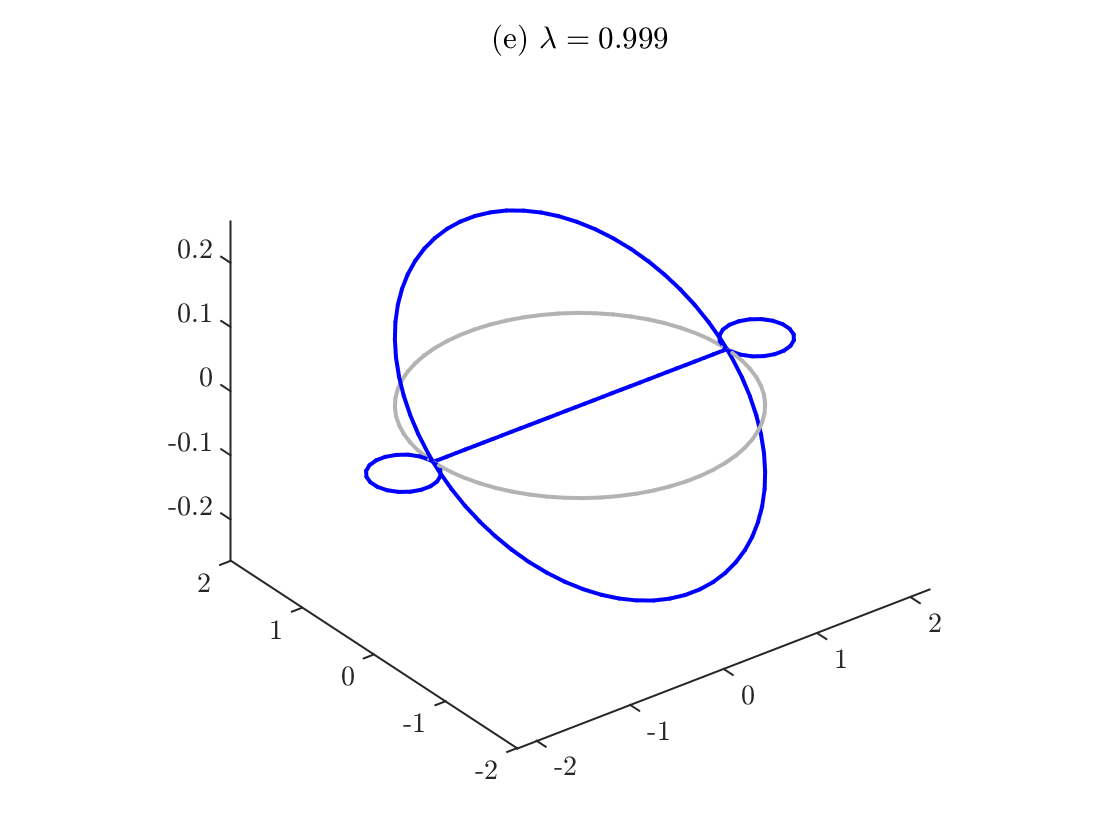

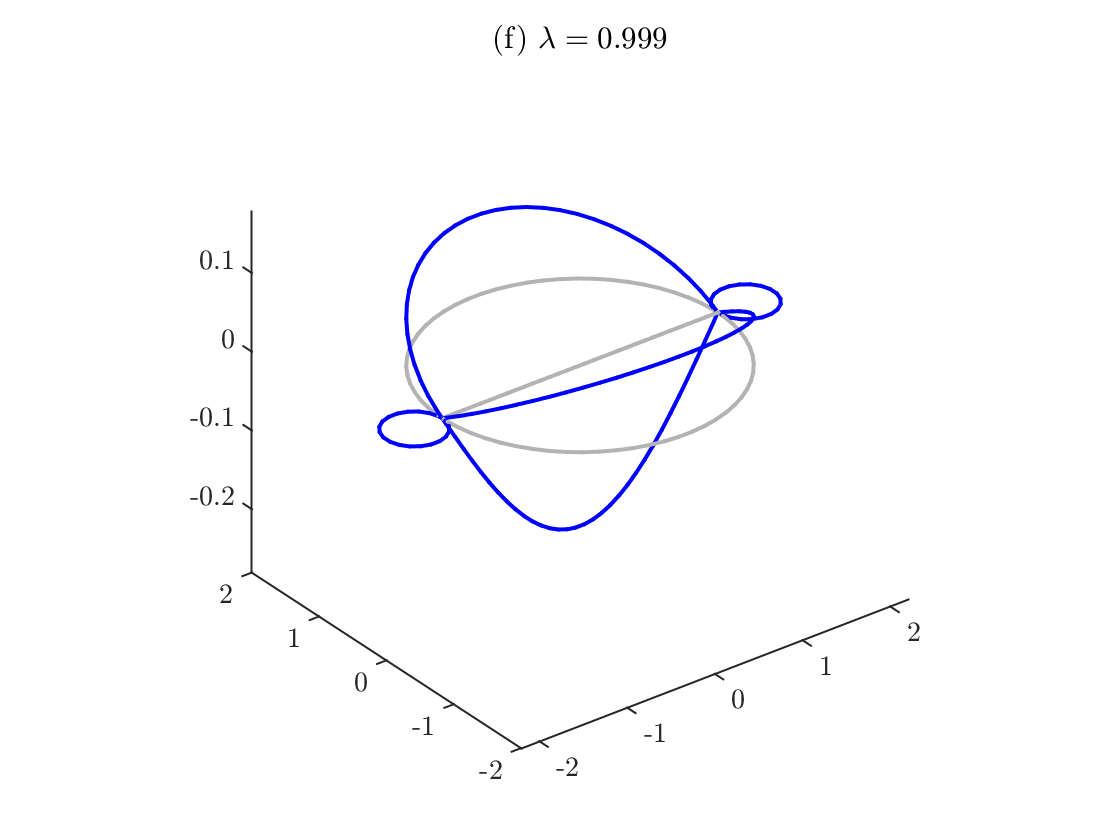

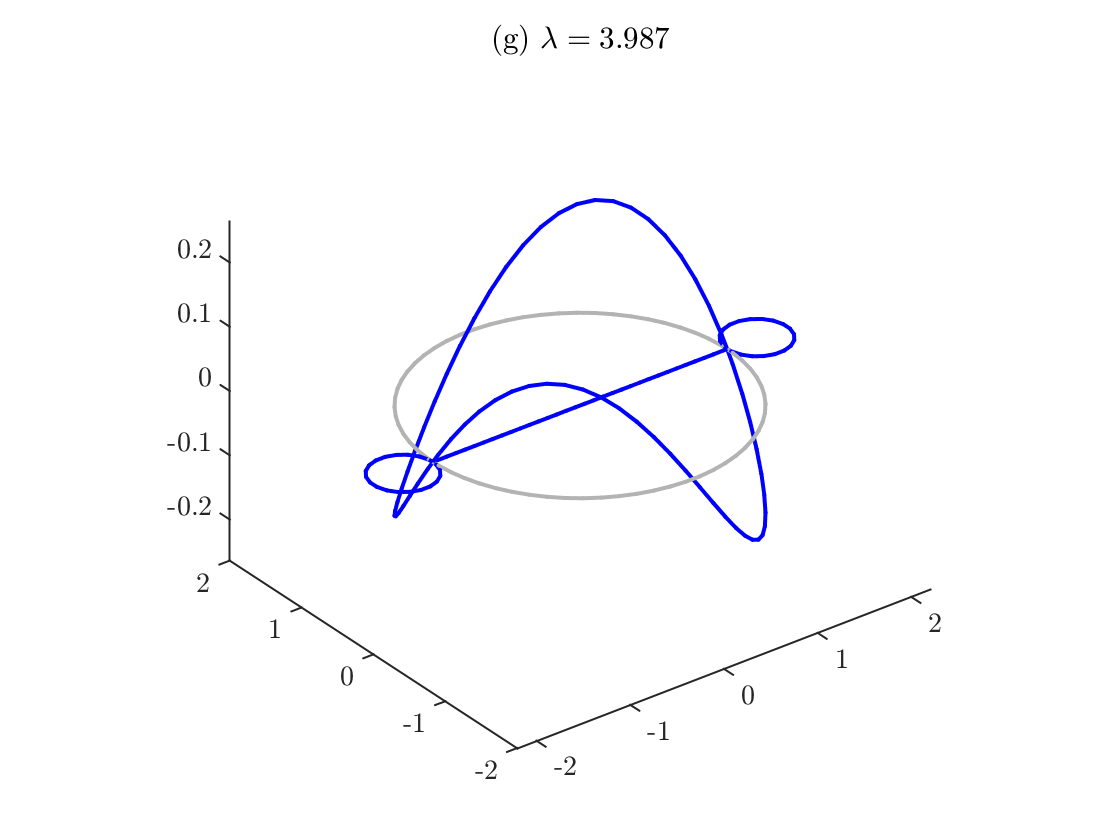

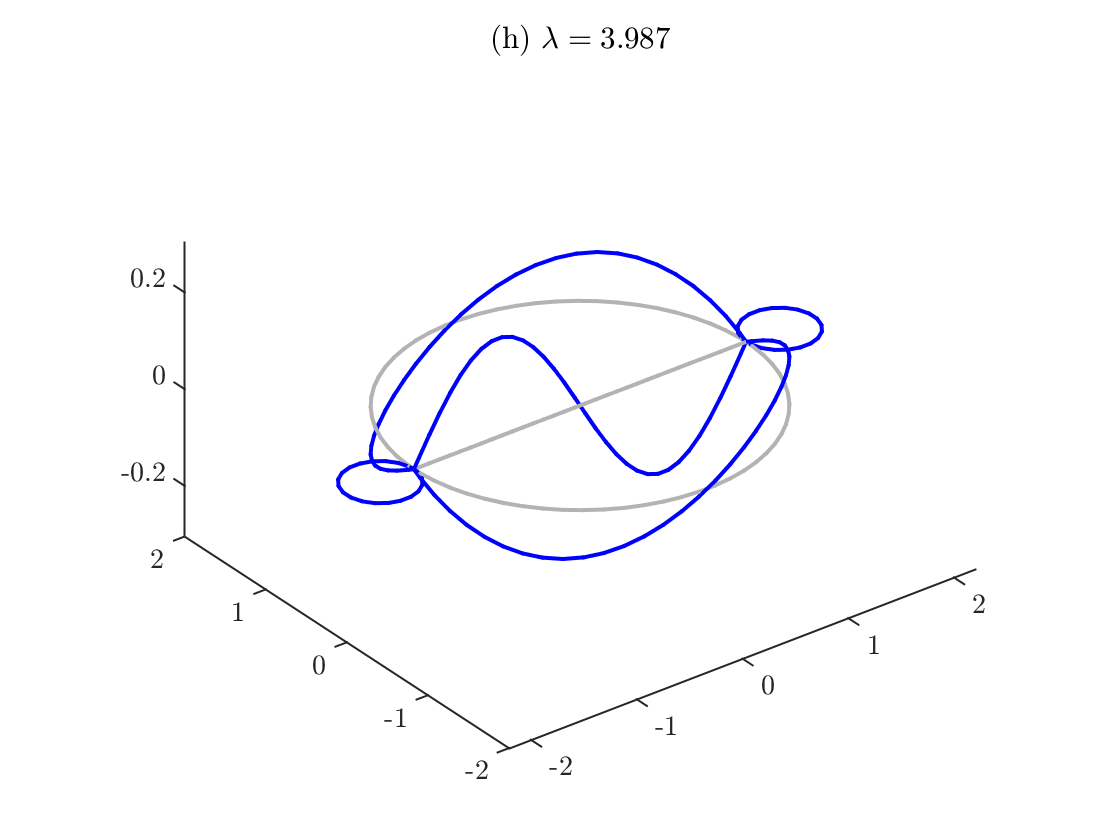

if ~isempty(doubles)
    nx=Phi.nx;
    for k=1:nToPlot/2
        vv=BMPResolveDoubles(V,doubles(k),Phi);
        figure
        Phi.plot(vv{1})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k-1), lambda(doubles(k))));
        figure
        Phi.plot(vv{2})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k), lambda(doubles(k))));
    end
end